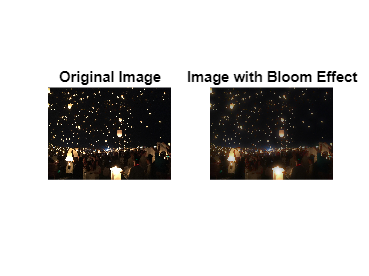

% Read the input image
inputImage = imread('FlyingLanterns.jpg'); % Replace 'your_image_path.jpg' with the actual path to your image

% Set bloom parameters
bloomIntensity = 0.5; % Adjust the bloom intensity
bloomRadius = 30; % Adjust the bloom radius

% Add bloom effect to the image
outputImage = addBloomEffect(inputImage, bloomIntensity, bloomRadius);

% Display the original and enhanced images
figure;
subplot(1, 2, 1);
imshow(inputImage);
title('Original Image');

subplot(1, 2, 2);
imshow(outputImage);
title('Image with Bloom Effect');

function outputImage = addBloomEffect(inputImage, bloomIntensity, bloomRadius)
    % Convert the image to double for computations
    inputImage = double(inputImage) / 255.0;

    % Extract the intensity channel (you may want to adapt this for different images)
    intensity = 0.3 * inputImage(:, :, 1) + 0.59 * inputImage(:, :, 2) + 0.11 * inputImage(:, :, 3);

    % Apply a Gaussian filter to the intensity channel to create a blurred version
    blurredIntensity = imgaussfilt(intensity, bloomRadius);

    % Enhance the bright regions by adding a fraction of the blurred image to the original
    enhancedIntensity = intensity + bloomIntensity * (blurredIntensity - intensity);

    % Combine the enhanced intensity with the original color channels
    outputImage = inputImage;
    for i = 1:3
        outputImage(:, :, i) = inputImage(:, :, i) .* (enhancedIntensity ./ intensity);
    end

    % Clip values to the valid range [0, 1]
    outputImage = min(max(outputImage, 0), 1);

    % Convert back to uint8 for display
    outputImage = uint8(outputImage * 255);
end
